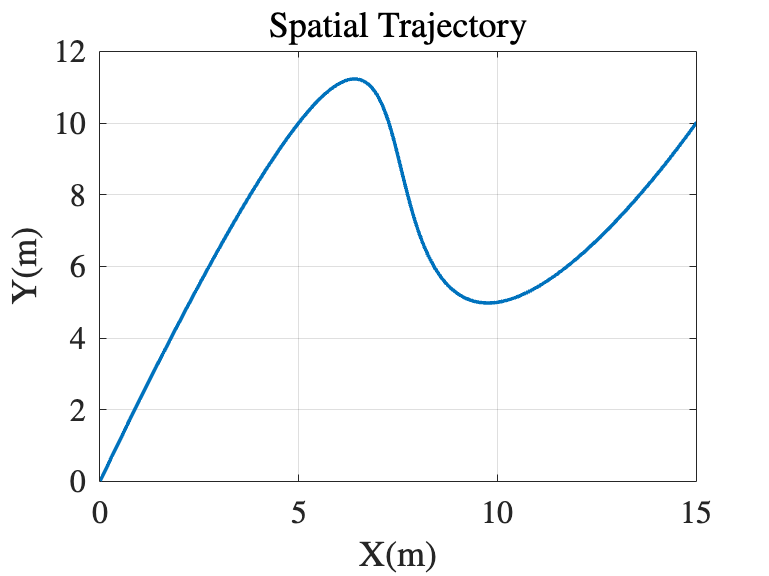

% Define simulation parameters
T = 10;
dt = 0.01;
t = 0:dt:T;

% Define vehicle properties
m = 1;
I = 1e-1;
r = 0.1;
g = 9.81;

% Define waypoints
wpts = [0 5 10 15;
        0 10 5 10];
tpts = [0 T/3 2*T/3 T];

[p, v, a, ~] = minsnappolytraj(wpts, tpts, numel(t));

figure
plot(p(1,:), p(2,:))
title('Spatial Trajectory')
xlabel('X(m)')
ylabel('Y(m)')

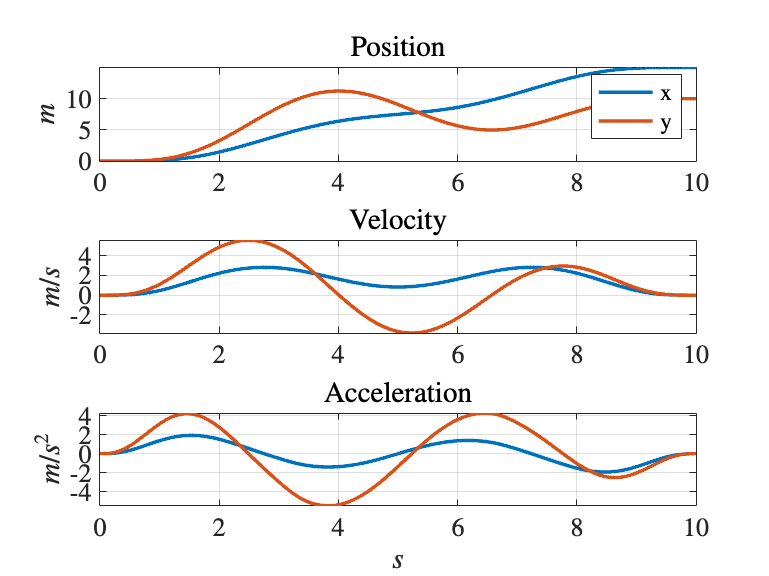


figure
subplot(3, 1, 1)
plot(t, p)
title('Position')
ylabel('$m$')
legend('x', 'y')

subplot(3, 1, 2)
plot(t, v)
title('Velocity')
ylabel('$m/s$')

subplot(3, 1, 3)
plot(t, a)
title('Acceleration')
ylabel('$m/s^2$')
xlabel('$s$')

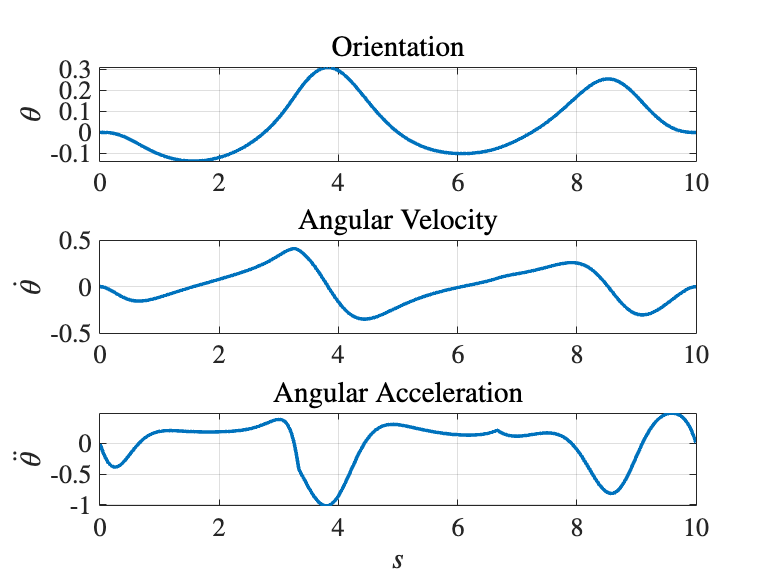


% Solve for rest of the states from spatial trajectory
x = p(1,:); y = p(2,:);
xdot = v(1,:); ydot = v(2,:);
xddot = a(1,:); yddot = a(2,:);

theta = atan2(-xddot, yddot + g);
thetadot = gradient(theta) / dt;
thetaddot = gradient(thetadot) / dt;

u1 = 1/2 * (m*(yddot + g) ./ cos(theta) + I * thetaddot / r);
u2 = 1/2 * (m*(yddot + g) ./ cos(theta) - I * thetaddot / r);

% Assembled reference trajectory
xref = [x; xdot; y; ydot; theta; thetadot];
uref = [u1; u2];

figure
subplot(3, 1, 1)
plot(t, theta)
title('Orientation')
ylabel('$\theta$')

subplot(3, 1, 2)
plot(t, thetadot)
title('Angular Velocity')
ylabel('$\dot{\theta}$')

subplot(3, 1, 3)
plot(t, thetaddot)
title('Angular Acceleration')
ylabel('$\ddot{\theta}$')
xlabel('$s$')

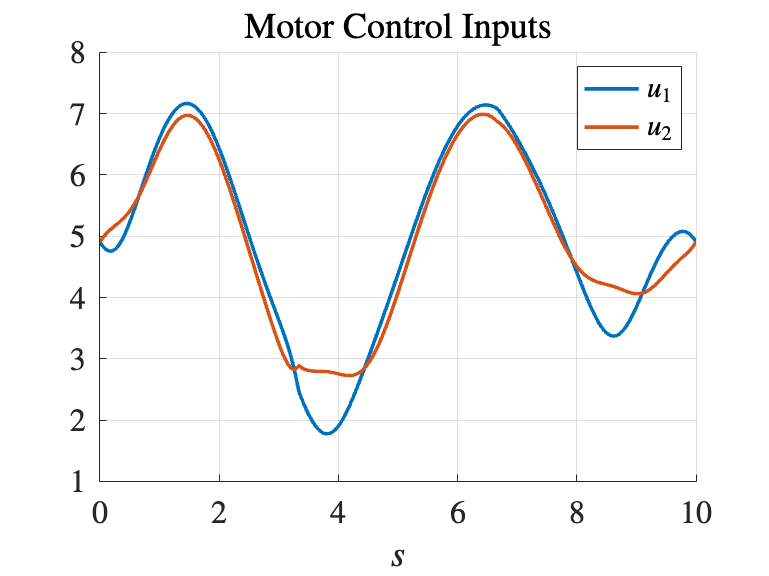


figure
hold on
plot(t, u1)
plot(t, u2)
legend('$u_1$', '$u_2$')
title('Motor Control Inputs')
xlabel('$s$')


% Assembled reference trajectory
xref = [x; xdot; y; ydot; theta; thetadot];
uref = [u1; u2];

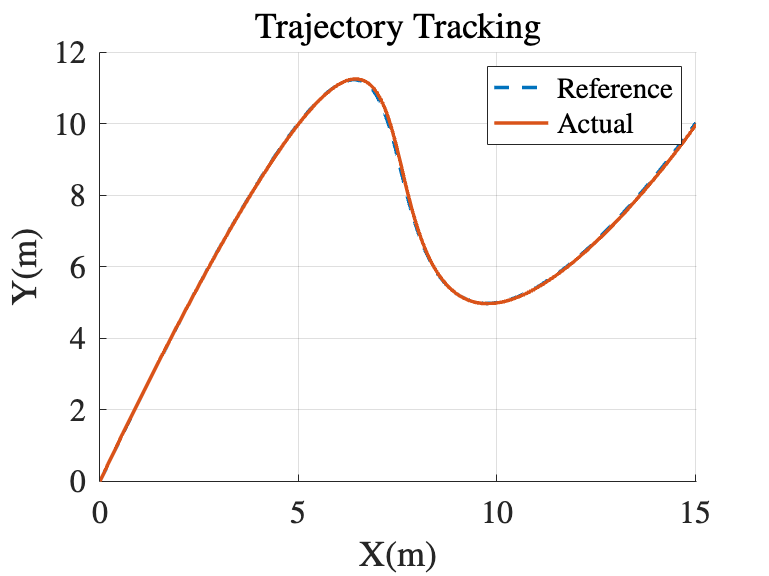

xnl = zeros(6, length(t));

u = [0; 0];

for i = 1:length(t) - 1

    xcur = xnl(:,i);
    xref_cur = xnl(:,i);

    % Compute tracking error against the closest point
    xe = xcur - xref_cur;

    % Compute tracking error
    xe = xnl(:,i) - xref(:,i);
    ue = u - uref(:,i);

    [A, B] = getLinearization(xref(:,i), uref(:,i), m, I, r);

    % Compute Control Gain using LQR
    Q = diag([1 1 1 1 1 1]);
    R = 100*diag([1 1]);

    sys = ss(A, B, eye(6), 0);

    k = lqr(sys, Q, R);
    
    ucur = uref(:,i) - k * xe;

    % Propagate the dynamics

    xcur = xnl(:,i);

    xdot = [xcur(2);
            -(ucur(1) + ucur(2)) * sin(xcur(5)) / m;
            xcur(4);
            (ucur(1) + ucur(2)) * cos(xcur(5)) / m - g;
            xcur(6);
            r*(ucur(1) - ucur(2)) / I];

    xnl(:,i+1) = xnl(:,i) + xdot * dt;

end

figure
hold on
plot(xref(1,:), xref(3,:), '--')
plot(xnl(1,:), xnl(3,:))
title('Trajectory Tracking')
legend('Reference', 'Actual')
xlabel('X(m)')
ylabel('Y(m)')

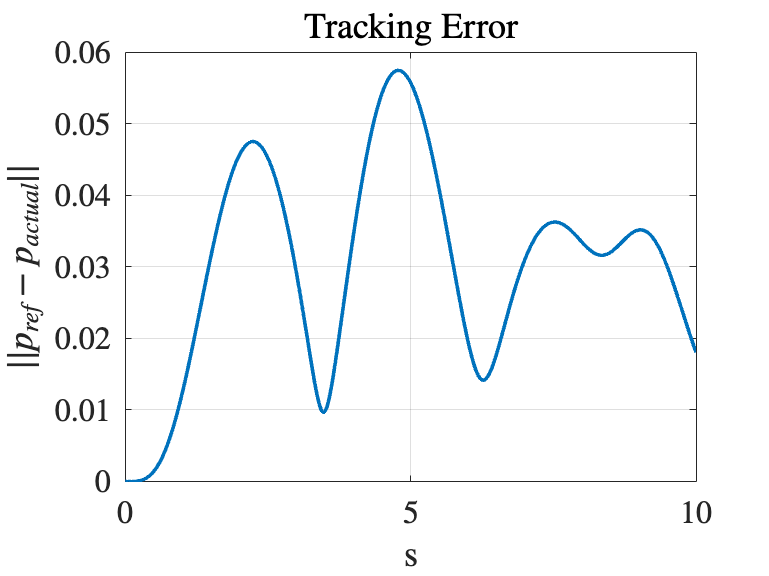


figure
plot(t, vecnorm(xnl([1,3],:) - xref([1,3],:)))
title('Tracking Error')
xlabel('s')
ylabel('$||p_{ref} - p_{actual}||$')